# **From data to insights **

- **Introduction to MATLAB** session

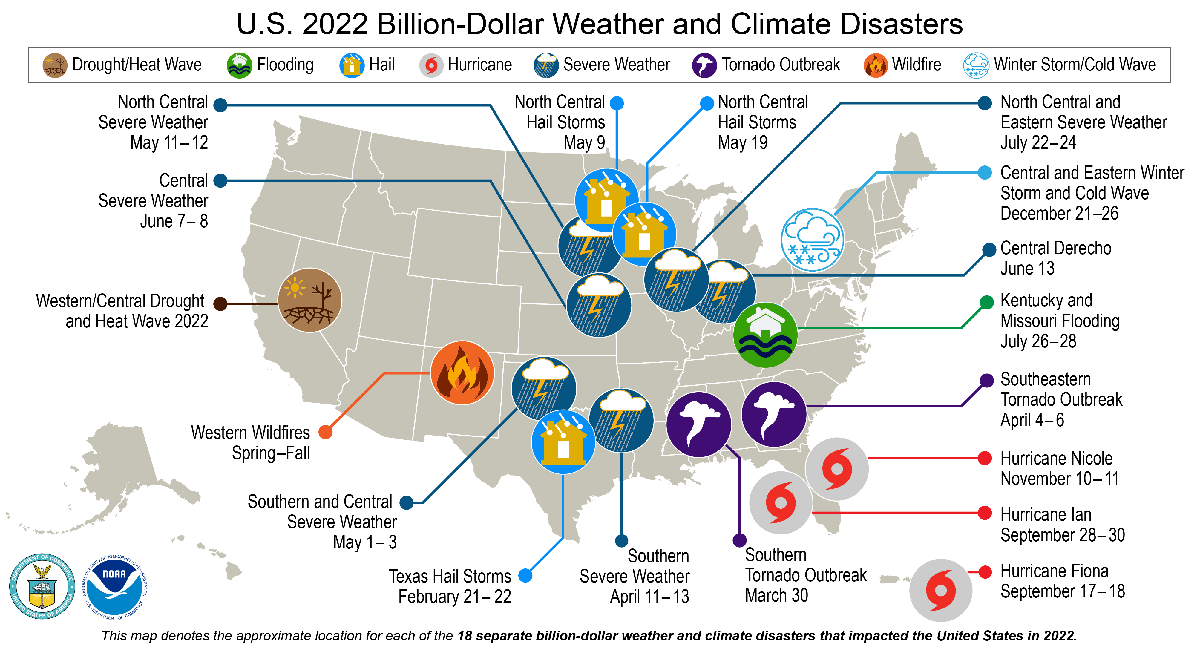

## 1) Access and Review the Data 

*The storm event data files are freely available from National Oceanic and Atmospheric Administration (NOAA): *[*https://www.ncei.noaa.gov/pub/data/swdi/stormevents/csvfiles/*](https://www.ncei.noaa.gov/pub/data/swdi/stormevents/csvfiles/) 

**For example:** StormEvents_details_d2022_c20230120.csv

writetable(myData,'myData.xls') table to xls

## **2)** Import the Data

[https://www.mathworks.com/help/matlab/import_export/import-data-interactively.html](https://www.mathworks.com/help/releases/R2020a/matlab/import_export/import-data-interactively.html)

myData = importfile("C:\Users\Andrea\Desktop\Info to send\1. Introduction to MATLAB\Demo\Final\allData\StormEvents_d2013.csv");

## 3) Visualize and Explore the Data

**What Weather Related Financial Costs are Reported?**

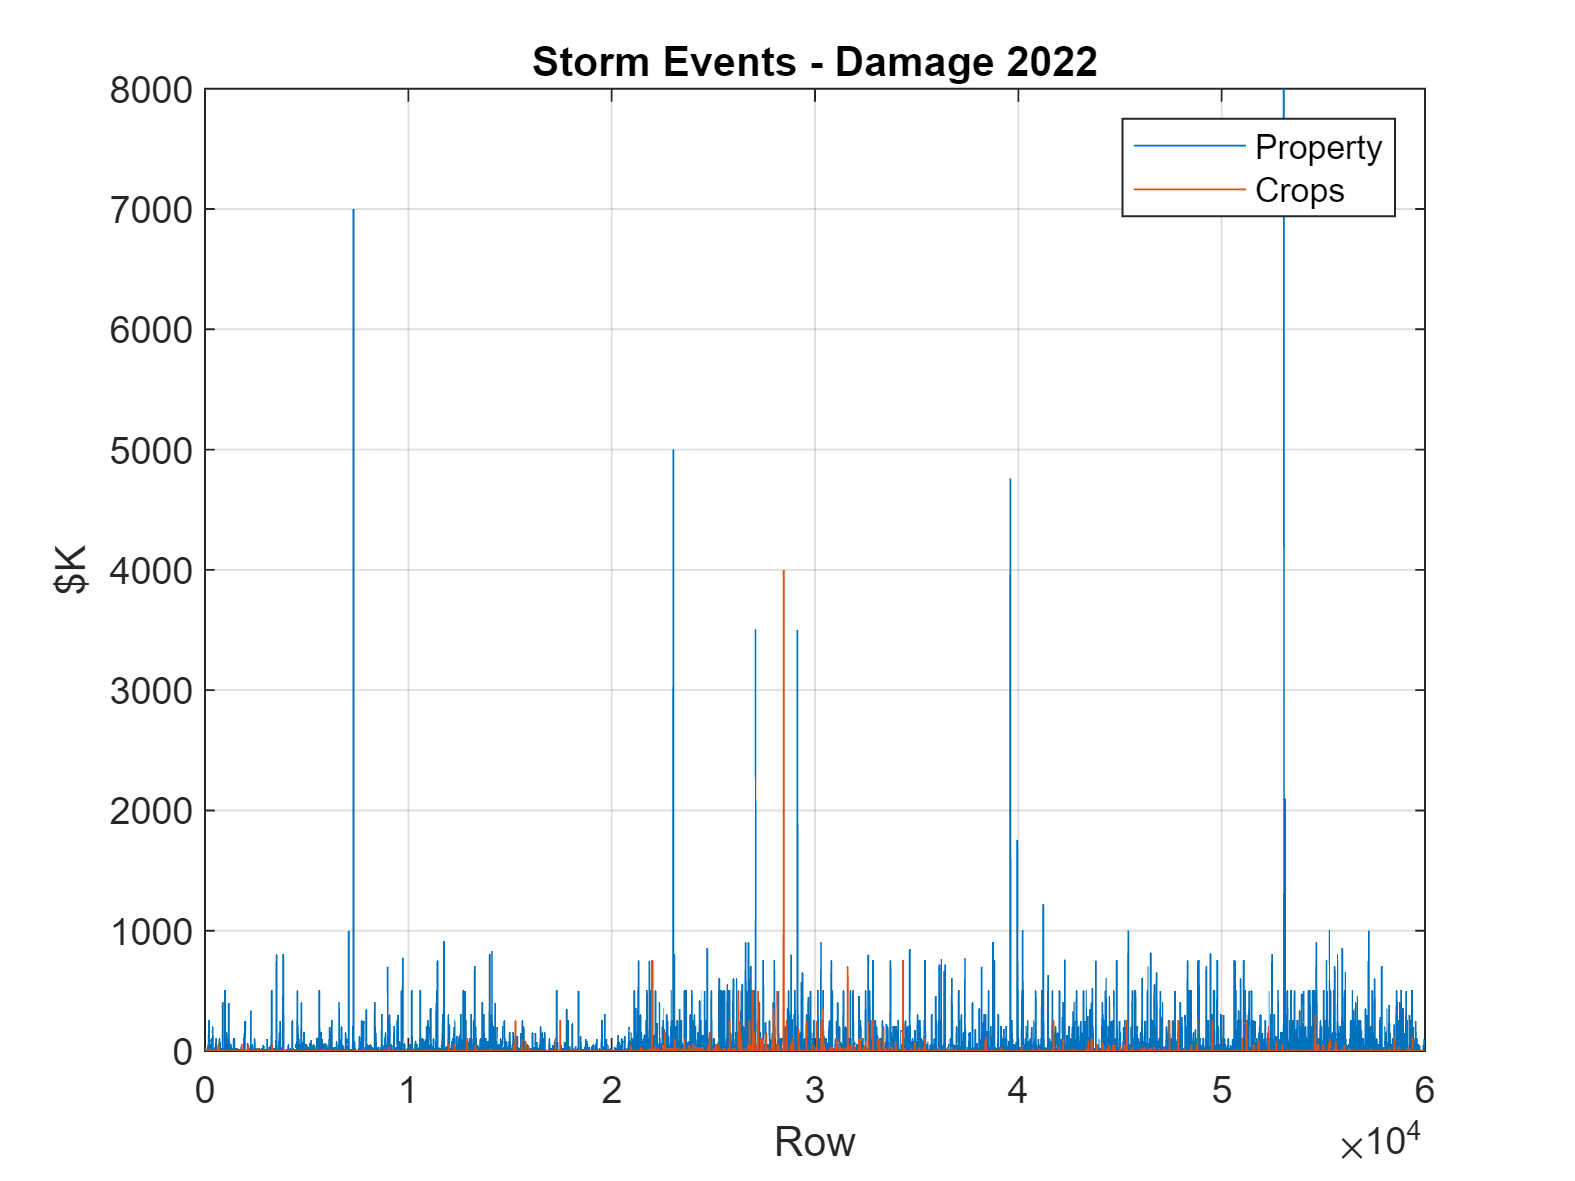

plot(myData.DAMAGE_PROPERTY,'DisplayName','Property');
hold on;
plot(myData.DAMAGE_CROPS,'DisplayName','Crops');
hold off;

legend('show');
ylabel('$K');
xlabel('Row');
grid("on")
title('Storm Events - Damage 2022');

**Observations:**

- More records reporting significant property damage than crop damage

- Fewer records have property damages > $500K

#### **What are the Most Frequent Weather Event Types?**

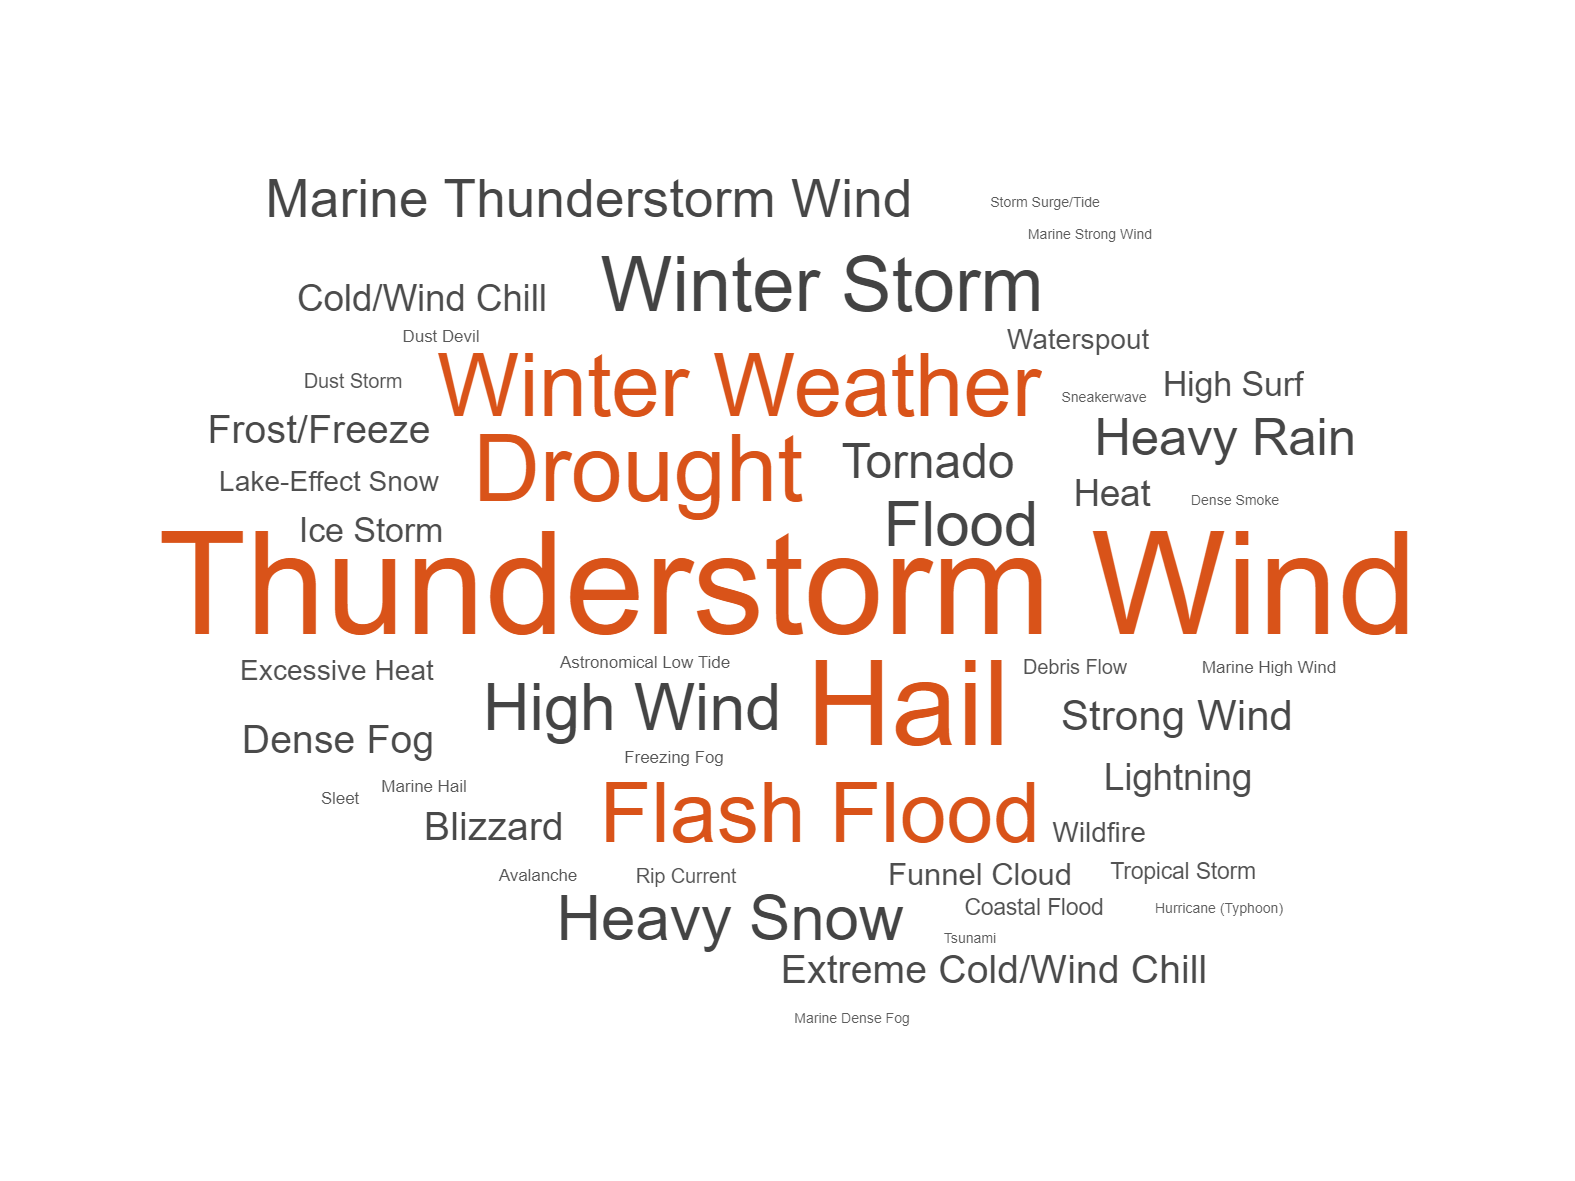

wordcloud(myData.EVENT_TYPE);

#### **When are the most events taken place?**

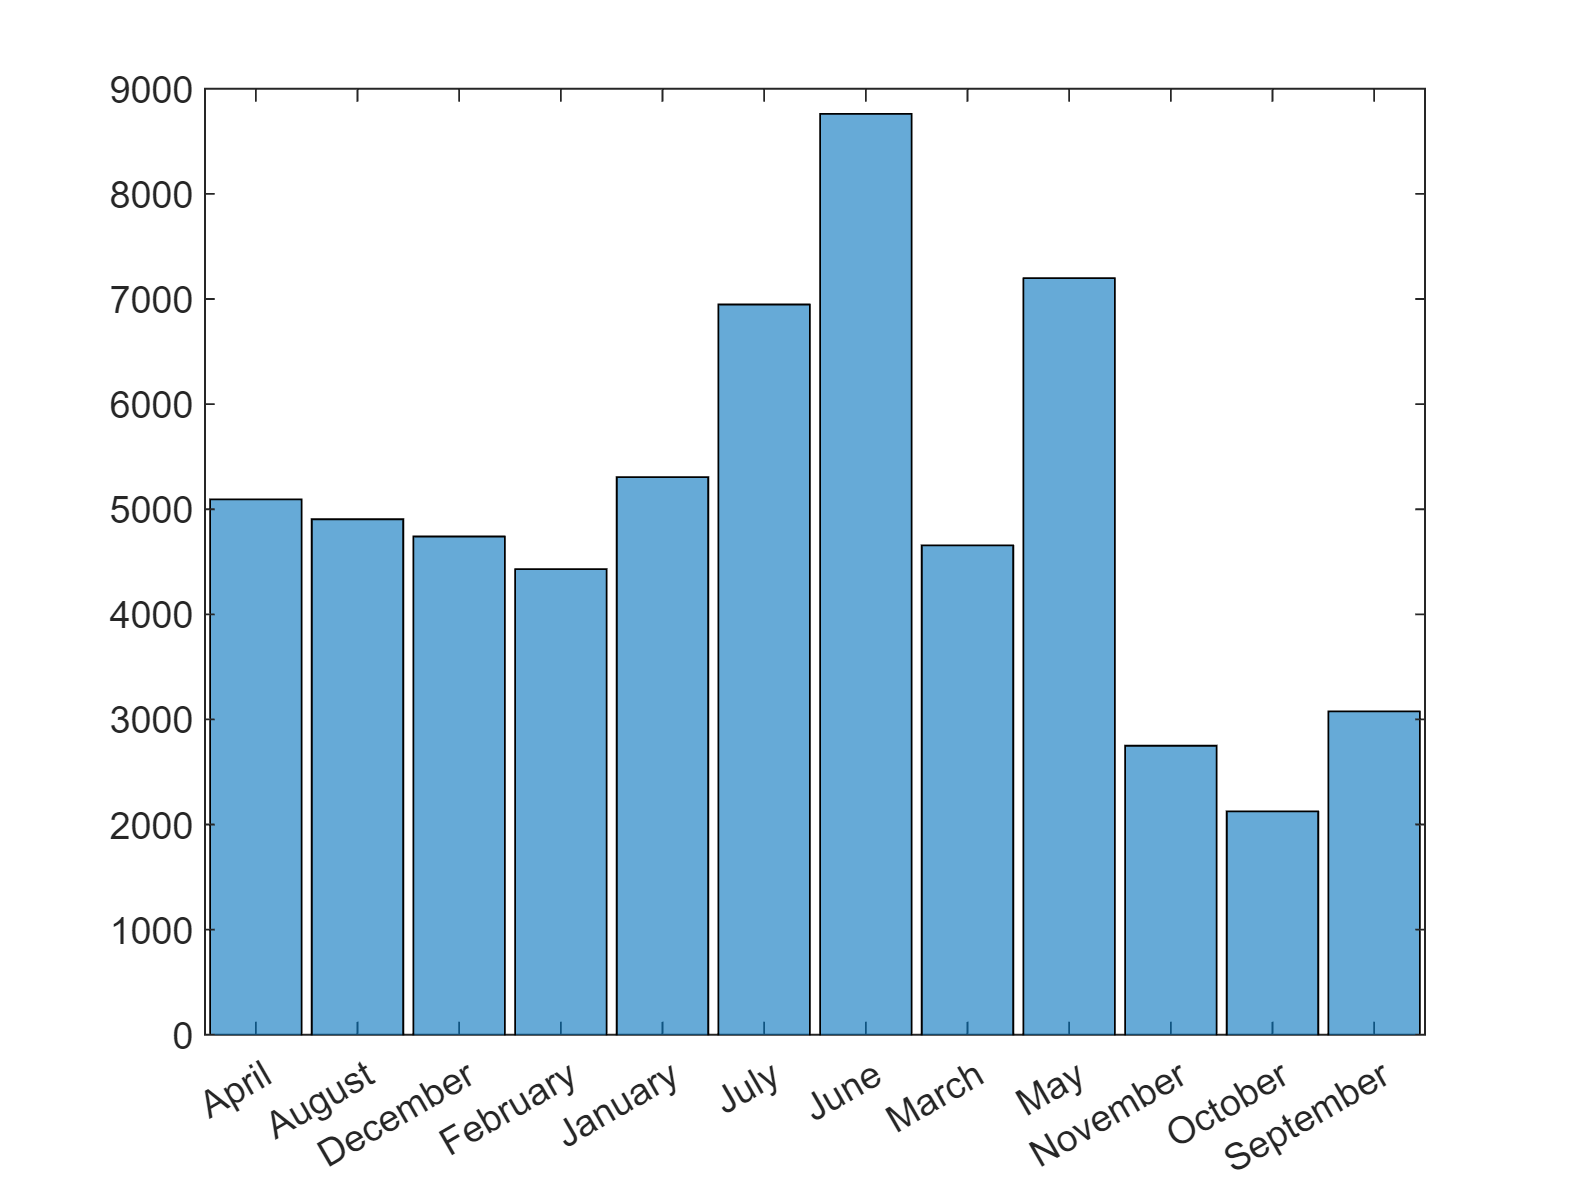

histogram(myData.MONTH_NAME)

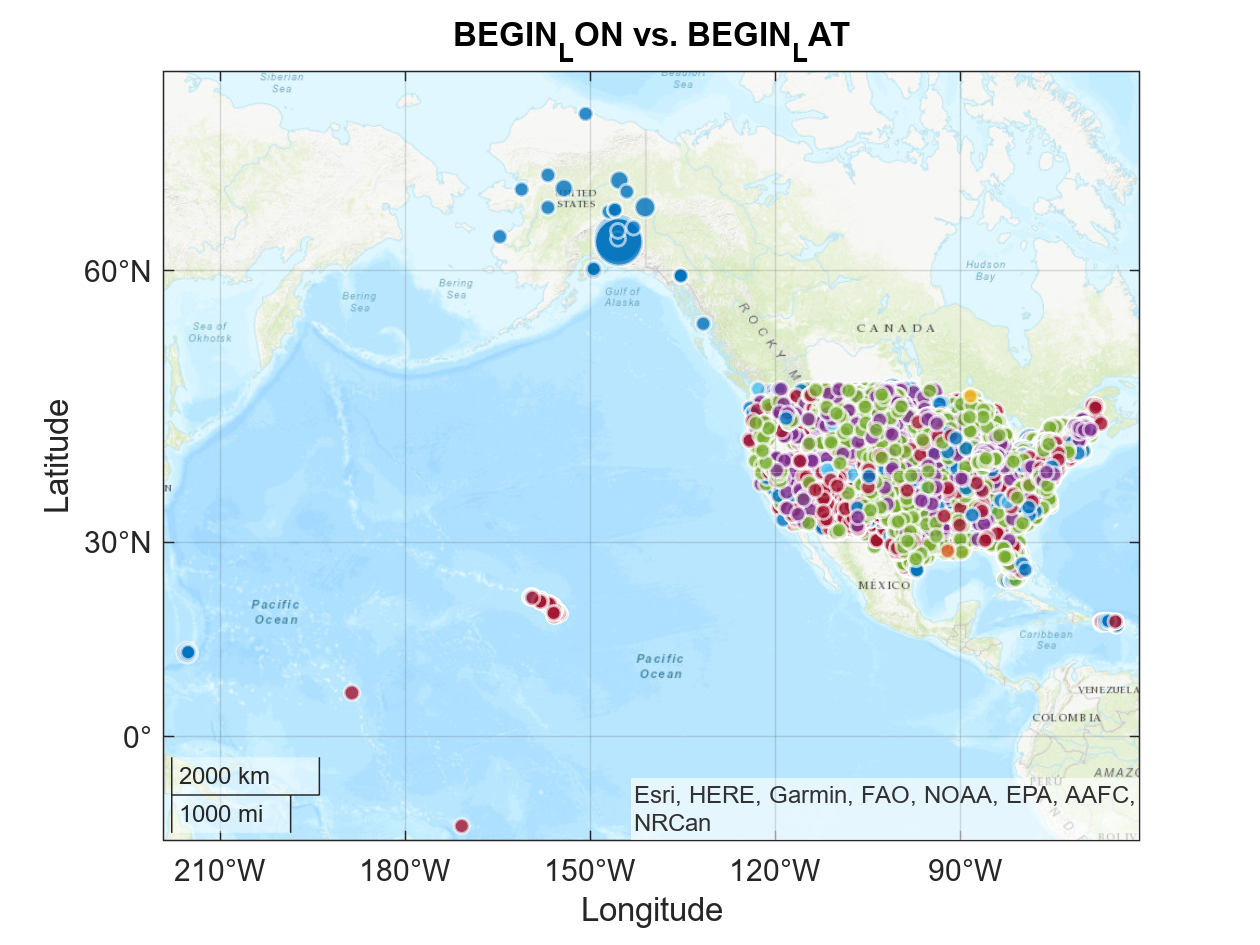

% Create geobubble of myData.BEGIN_LAT and myData.BEGIN_LON
gb = geobubble(myData.BEGIN_LAT,myData.BEGIN_LON,myData.DAMAGE_PROPERTY,myData.EVENT_TYPE,"Basemap","topographic");

% Add title
title("BEGIN_LON vs. BEGIN_LAT")

## 4) Determine Amount of Data to be Used for Analysis 

**Goal: Identify Locations Reporting the Higher Property Damages**

[https://www.mathworks.com/help/matlab/ref/findlocalextrema.html](https://www.mathworks.com/help/matlab/ref/findlocalextrema.html)

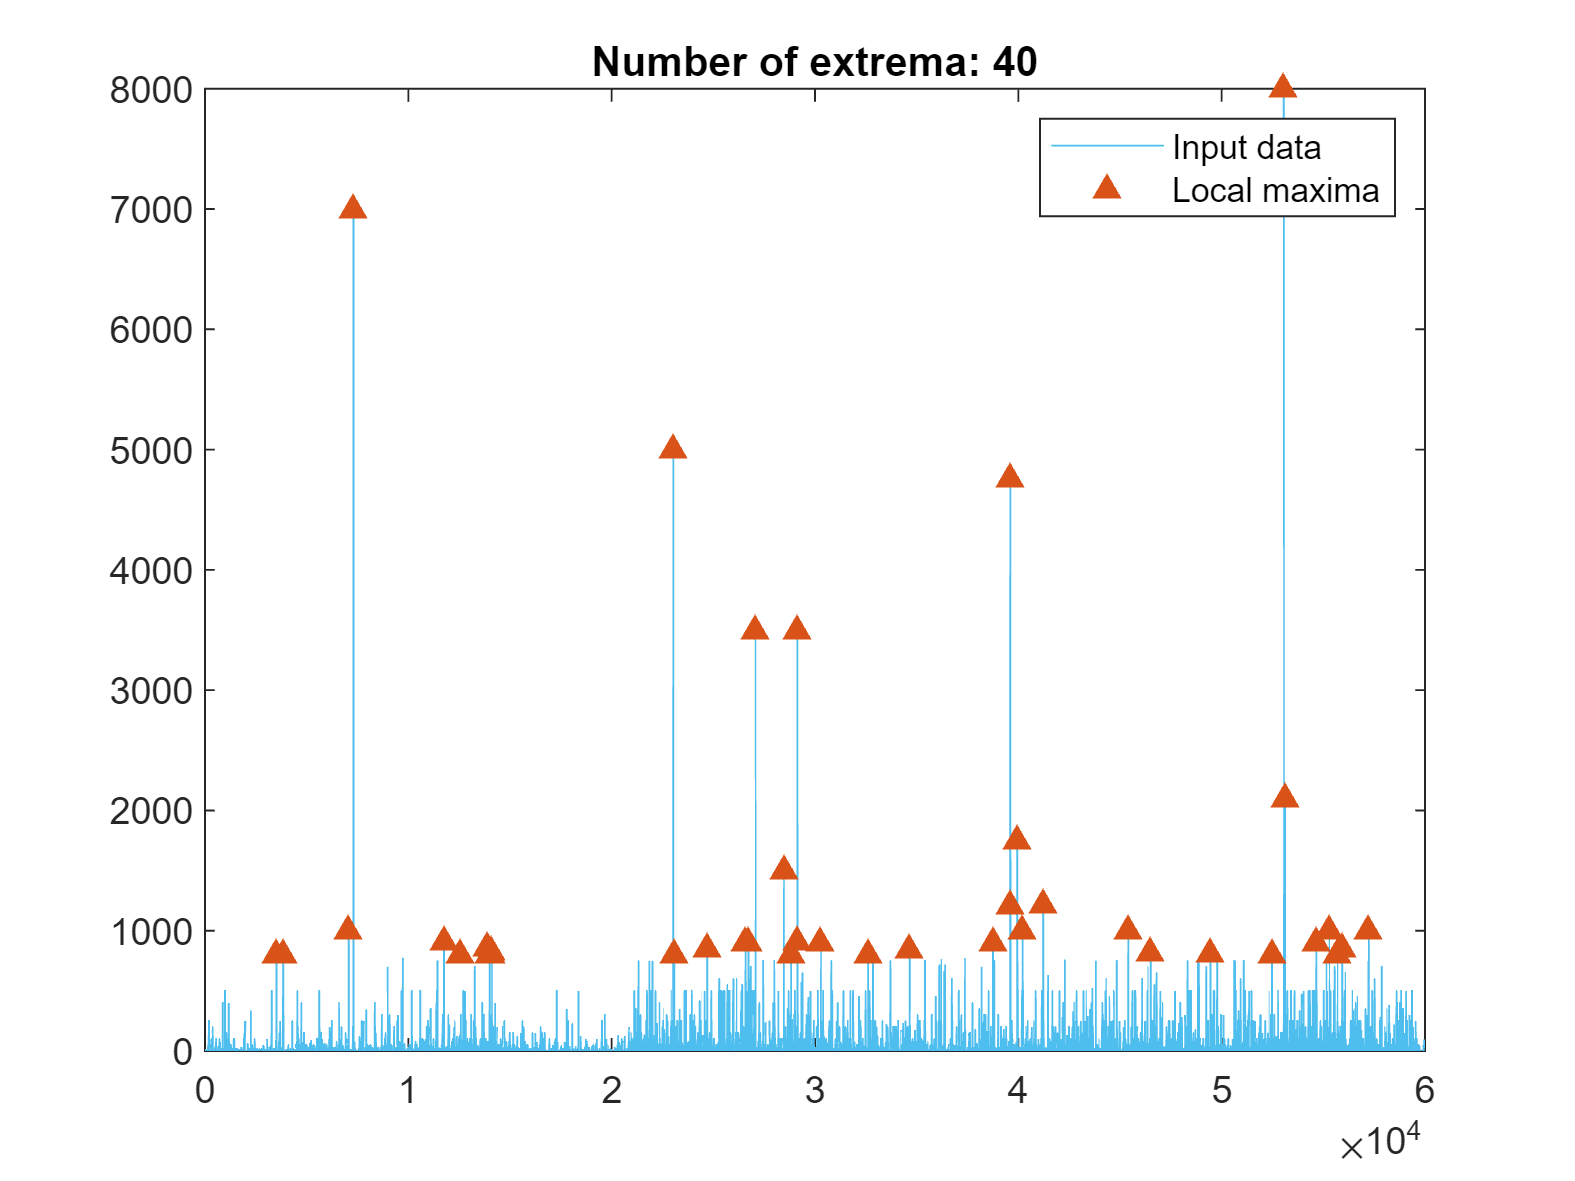

% Find local maxima
maxIndices = islocalmax(myData.DAMAGE_PROPERTY,"MinProminence",800,...
    "MaxNumExtrema",100);

% Display results
figure
plot(myData.DAMAGE_PROPERTY,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on

% Plot local maxima
plot(find(maxIndices),myData.DAMAGE_PROPERTY(maxIndices),"^",...
    "Color",[217 83 25]/255,"MarkerFaceColor",[217 83 25]/255,...
    "DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices))
hold off
legend

## **Subset of New Data to Report Maximum Damage Areas**

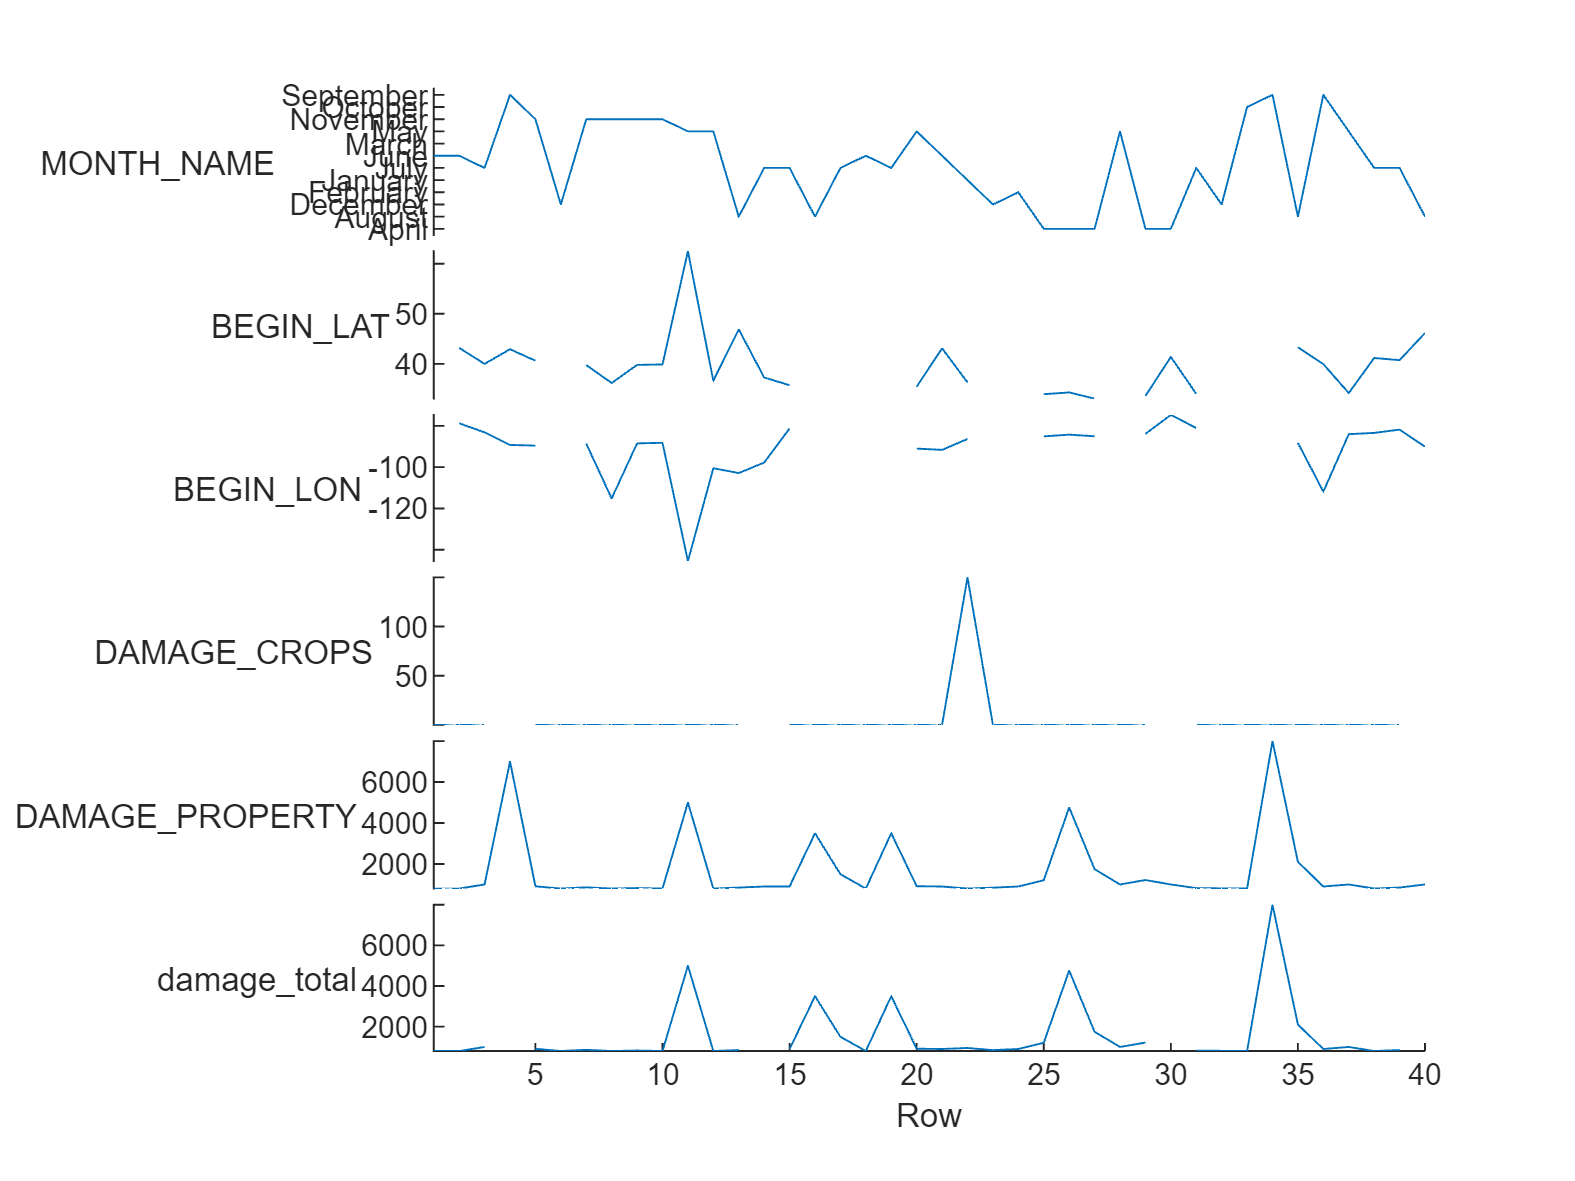

costlyStormEvents = myData(maxIndices,["MONTH_NAME","BEGIN_LAT","BEGIN_LON","DAMAGE_CROPS","DAMAGE_PROPERTY"]);
costlyStormEvents.damage_total = costlyStormEvents.DAMAGE_CROPS + costlyStormEvents.DAMAGE_PROPERTY;
stackedplot(costlyStormEvents);

NE = myData(maxIndices,"EVENT_TYPE")

NE = 40×1 table
       EVENT_TYPE    
    _________________

    Wildfire         
    Flood            
    Thunderstorm Wind
    Thunderstorm Wind
    Tornado          
    Winter Weather   
    Tornado          
    Heavy Rain       
    Tornado          
    Tornado          
    Flood            
    Thunderstorm Wind
    Thunderstorm Wind
    Thunderstorm Wind
    Flash Flood      
    Wildfire         


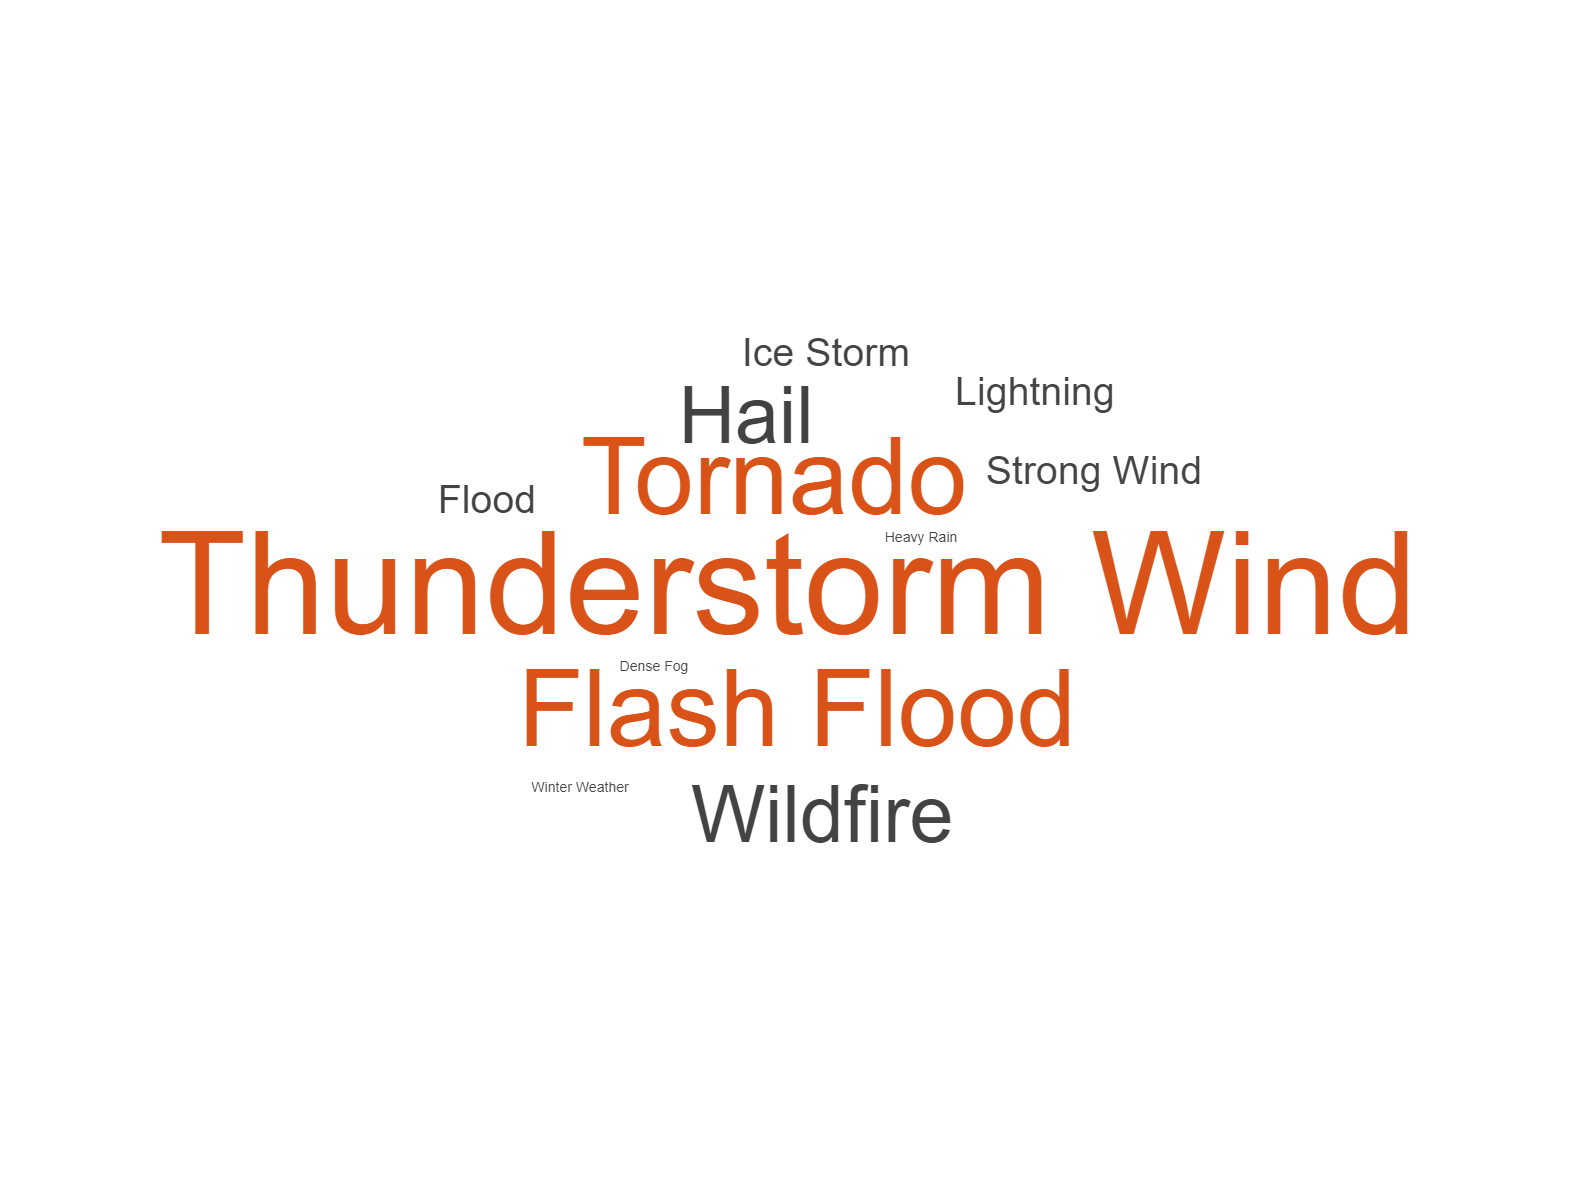

wordcloud(NE.EVENT_TYPE);

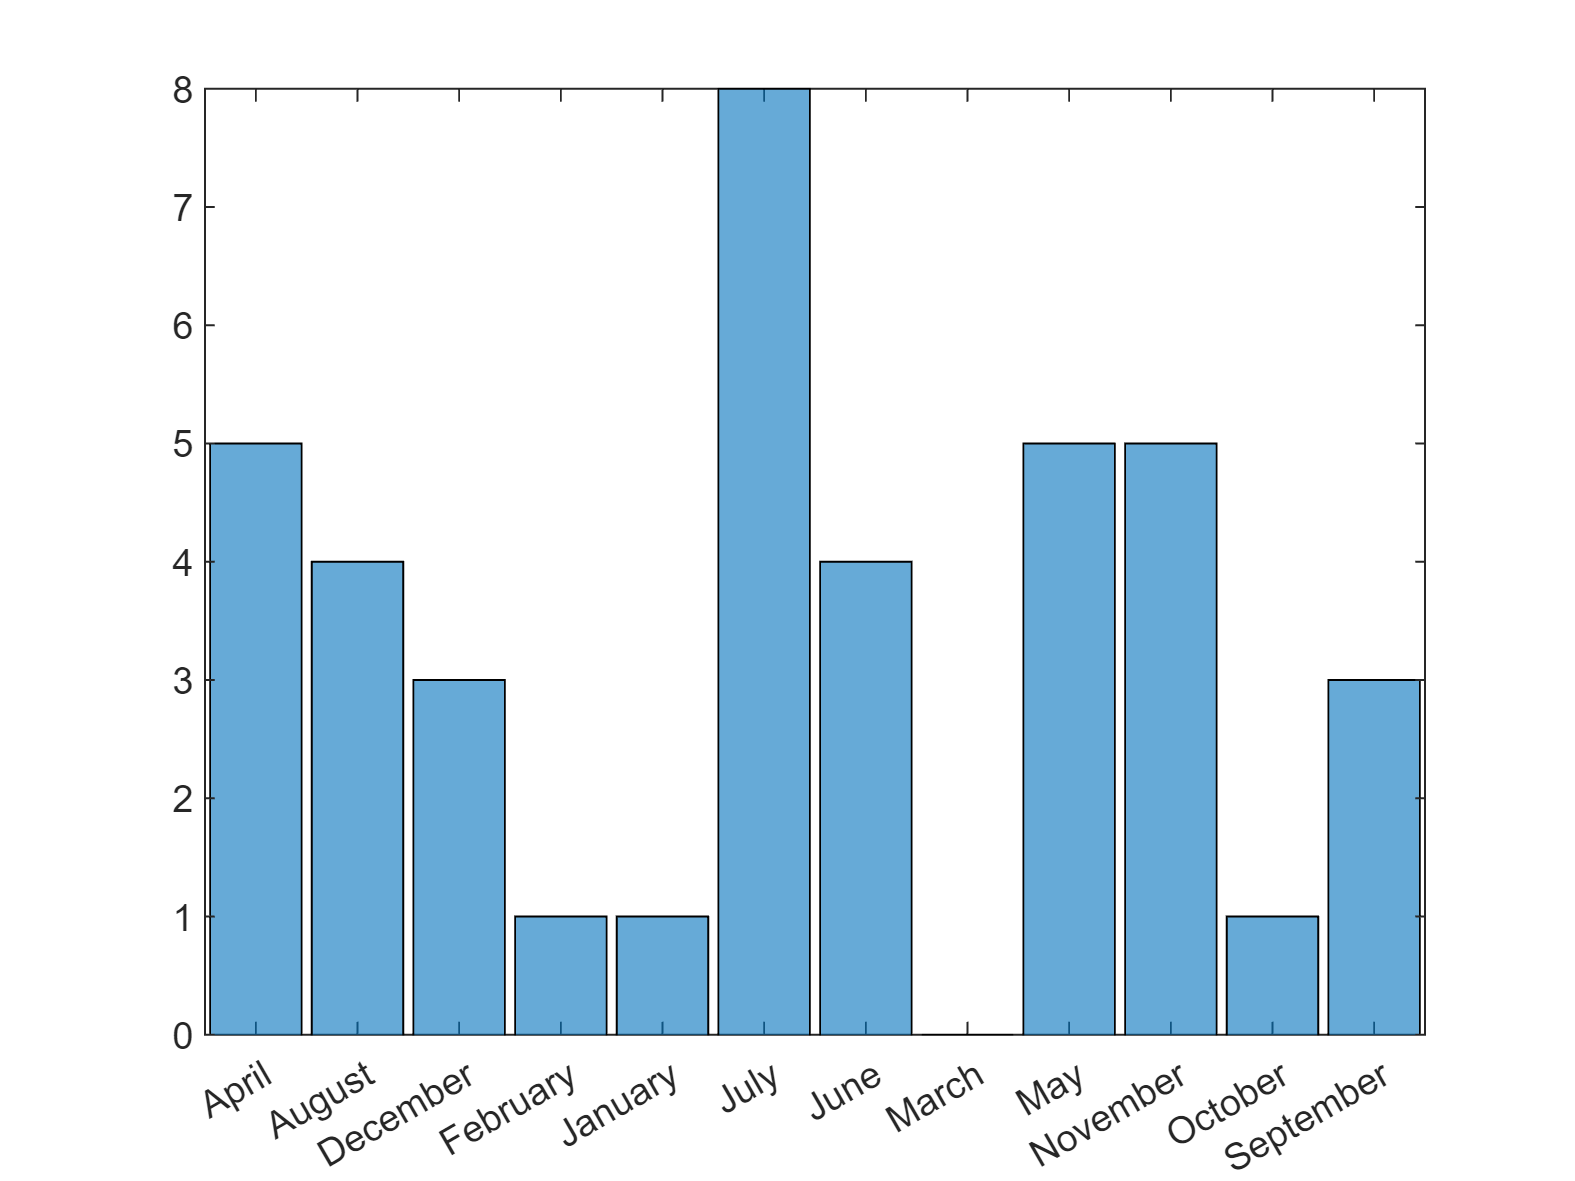

histogram(costlyStormEvents.MONTH_NAME);

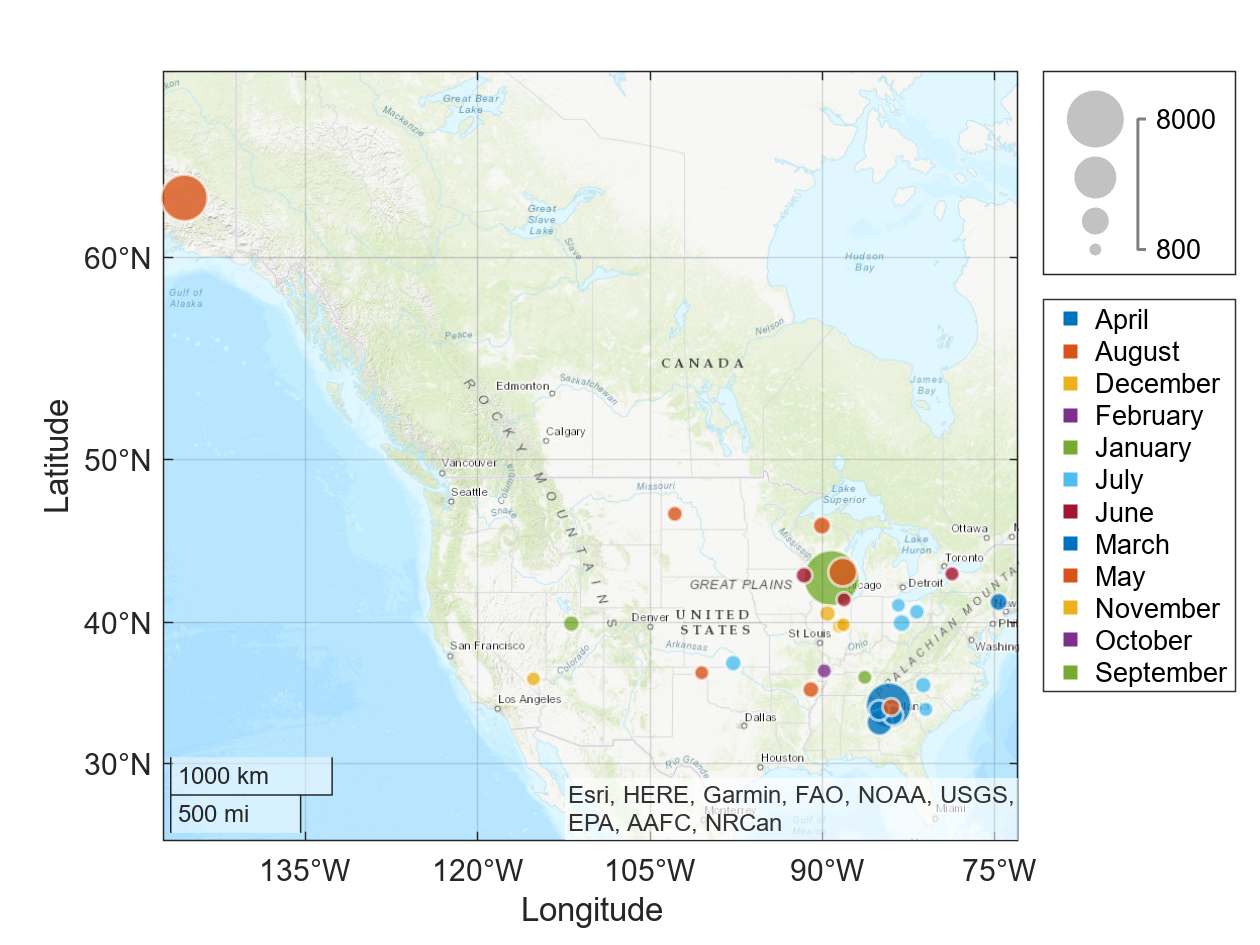

gb3 = geobubble(costlyStormEvents.BEGIN_LAT,costlyStormEvents.BEGIN_LON,costlyStormEvents.DAMAGE_PROPERTY,costlyStormEvents.MONTH_NAME,"Basemap","topographic");

## **5)** Implement Analysis of Data 

**Could Machine Learning algorithms be used to develop a predictive model from this example dataset?**

[https://www.mathworks.com/products/statistics.html](https://www.mathworks.com/products/statistics.html)

[https://www.mathworks.com/help/stats/classificationlearner-app.html](https://www.mathworks.com/help/stats/classificationlearner-app.html)

% dsAllStormEvents = datastore("*.xlsx","TextType","string")
% processed=preprocessLargeDataset
%myData2train = importfile_xlsx("myData2train.xlsx");

## 6) View a Report of the Analysis 

[https://www.mathworks.com/help/matlab/live-scripts-and-functions.html](https://www.mathworks.com/help/matlab/live-scripts-and-functions.html)

[https://www.mathworks.com/help/matlab/matlab_prog/share-live-scripts.html](https://www.mathworks.com/help/matlab/matlab_prog/share-live-scripts.html)

## **7)** Next Steps - Available Resources

%web('www.mathworks.com');

Custom Proof of Concept: 

***************************** DISCLAIMER ***************************** 

The purpose of these code samples is to illustrate the capabilities of MathWorks' products. Code samples that are not explicitly included in MathWorks' products have not been fully tested up to MathWorks' standards and should be independently verified. MathWorks and its employees are not liable for any loss or damage of any kind incurred as a result of the use of this content. 

***************************** DISCLAIMER *****************************